# RefMap quasi-loudness transform development

This script calculates the Sottek Hearing Model loudness values associated with the 2023 ISO 226 equal-loudness contours, then examines and optimises an adaptation of the Zwicker loudness transform function to match more closely with the apparent transform obtained with Sottek loudness.

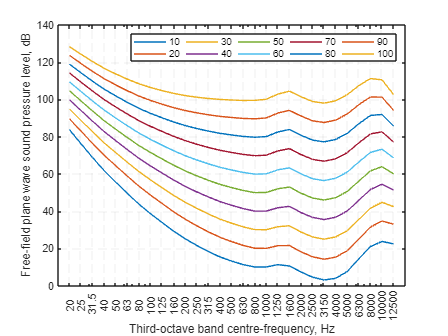

% Generate the ISO 226:2023 sound pressure values corresponding with each
% phon level and third-octave band centre-frequency

% ISO 532-1 Table A.6: critical band levels at threshold in quiet
levelThresQCB5321 = [30, 18, 12, 8, 7, 6, 5, 4,...
                     3, 3, 3, 3, 3, 3, 3, 3, 3, 3, 3, 3];

% ISO 532-1 Table A.7: critical bandwidth vs. 1/3-octave bandwidth
% adjustment
critBWAdjust = [-0.25, -0.6, -0.8, -0.8, -0.5, 0, 0.5, 1.1, 1.5, 1.7,...
                1.8, 1.8, 1.7, 1.6, 1.4, 1.2, 0.8, 0.5, 0, -0.5];

% ISO 532-3 Table 2: third-octave band levels at threshold in quiet
% (extended down to 25 Hz according to ISO 532-3 software implementation)
levelThresQTOB5323 = [28.18, 28.18, 28.18, 28.18, 23.9, 19.2, 15.68,...
                      12.67, 10.09, 8.08, 6.3, 5.3, 4.5, 3.63, 3.63,...
                      3.63, 3.63, 3.63, 3.63, 3.63, 3.63, 3.63, 3.63,...
                      3.63, 3.63, 3.63, 3.63, 3.63];

levelThresQCB5323 = [10*log10(sum(10.^(levelThresQTOB5323(1:6)/10))),...
                     10*log10(sum(10.^(levelThresQTOB5323(7:9)/10))),...
                     10*log10(sum(10.^(levelThresQTOB5323(10:11)/10))),...
                     levelThresQTOB5323(12:end)];

levelThresQCB5323 = levelThresQCB5323 - critBWAdjust;

% ISO 532-3 Table 2: third-octave band levels at threshold in quiet
% (extended down to 25 Hz by extrapolation considering ISO 389-7 LTQ)
levelThresQTOB53233897 = [45, 39, 33, 28.18, 23.9, 19.2, 15.68,...
                          12.67, 10.09, 8.08, 6.3, 5.3, 4.5, 3.63, 3.63,...
                          3.63, 3.63, 3.63, 3.63, 3.63, 3.63, 3.63, 3.63,...
                          3.63, 3.63, 3.63, 3.63, 3.63];

levelThresQCB53233897 = [10*log10(sum(10.^(levelThresQTOB53233897(1:6)/10))),...
                         10*log10(sum(10.^(levelThresQTOB53233897(7:9)/10))),...
                         10*log10(sum(10.^(levelThresQTOB53233897(10:11)/10))),...
                         levelThresQTOB53233897(12:end)];

levelThresQCB53233897 = levelThresQCB53233897 - critBWAdjust;

% third-octave band frequencies
[fm, f1, f2, fn] = noctf([20, 12500], 3);

% critical band frequencies (taking central fn as representative)
fnCB = [fn(4), fn(9), fn(12:end)];

% ISO 226 equal loudness curve parameters
alphaf = [0.635, 0.602, 0.569, 0.537, 0.509, 0.482, 0.456, 0.433, 0.412, 0.391,...
          0.373, 0.357, 0.343, 0.330, 0.320, 0.311, 0.303, 0.300, 0.295,...
          0.292, 0.290, 0.290, 0.289, 0.289, 0.289, 0.293, 0.303, 0.323, 0.354];

luf = [-31.5, -27.2, -23.1, -19.3, -16.1, -13.1, -10.4, -8.20, -6.30, -4.60,...
       -3.20, -2.10, -1.20, -0.50, 0.000, 0.400, 0.500, 0.000, -2.70, -4.20,...
       -1.20, 1.400, 2.300, 1.000, -2.30, -7.20, -11.2, -10.9, -3.50];

threshf = [78.1, 68.7, 59.5, 51.1, 44.0, 37.5, 31.5, 26.5, 22.1, 17.9, 14.4,...
           11.4, 8.60, 6.20, 4.40, 3.00, 2.20, 2.40, 3.50, 1.70, -1.3, -4.2,...
           -6.0, -5.4, -1.5, 6.00, 12.6, 13.9, 12.3];

phonRange = [10; 20; 30; 40; 50; 60; 70; 80; 90; 100];

phonRange1k = [0; 2.2; 4; 5; 7.5; 10; 15; 20; 25; 30; 35; 40; 45; 50; 55; 60; 65; 70; 75; 80; 85;...
               90; 95; 100; 105; 110; 115; 120];

phon2spl = 10./alphaf.*log10((4*10^-10).^(0.3 - alphaf).*(10.^(0.03*repmat(phonRange, 1, length(fm))) - 10^0.072)...
           + (10.^(alphaf.*(threshf + luf)/10))) - luf;

spl2rms = 2e-5*10.^(phon2spl/20);

fig = figure;
semilogx(fm, phon2spl);
grid('on')
set(gca, 'XTick', fn, 'XTickLabel', fn, 'XLim', [16, 16e3], 'XMinorTick', 'off', 'GridAlpha', 0.05',...
    'GridLineStyle', '--', 'XMinorGrid', 'off')
xlabel("Third-octave band centre-frequency, Hz")
ylabel("Free-field plane wave sound pressure level, dB")
legend(string(phonRange), 'NumColumns', floor(length(phonRange)/2))

% generate a 5-s sinusoid corresponding with each sound pressure level in the
% spl2rms array, and calculate its Sottek loudness, without any outer-middle ear
% filtering
fs = 48e3;
t = linspace(0, 5 - 1/fs, 5*fs);
signal2sone = zeros(size(spl2rms));
iiS = size(spl2rms, 1);
jjS = size(spl2rms, 2);
parfor ii = 1:iiS
    for jj = 1:jjS
        signal = sqrt(2)*spl2rms(ii, jj).*sin(2*pi*fn(jj)*t);
        loudnessSHM = acousticSHMLoudness(signal, fs, 2, 'noEar', false, false, false);
        signal2sone(ii, jj) = loudnessSHM.loudnessPowAvg;
    end
end

% reduce array to critical band 'centres'
signal2soneCB = [signal2sone(:, 4), signal2sone(:, 9), signal2sone(:, 12:end)];
phon2splCB = [phon2spl(:, 4), phon2spl(:, 9), phon2spl(:, 12:end)];

% generate a higher resolution for 1 kHz sinusoid

spl2rms1k = 2e-5*10.^(phonRange1k/20);

signal2sone1k = zeros([length(spl2rms1k), 1]);
parfor ii = 1:length(phonRange1k)
    signal = sqrt(2)*spl2rms1k(ii).*sin(2*pi*1000*t);
    loudnessSHM = acousticSHMLoudness(signal, fs, 2, 'noEar', false, false, false);
    signal2sone1k(ii) = loudnessSHM.loudnessPowAvg;
end

% optimisation of 1k function for Sottek Hearing Model
x01k = [0.103589607, 1.5016, 0.2552, 0.20627, -0.01067, 108.66, -17.03];
lb1k = [0.1, 1, 0.1, 0.1, -0.05, -1e5, -1e5];
ub1k = [0.11, 2, 0.4, 0.4, 0.025, 1e5, 1e5];

optimFunc = @(q, X) loudnessTransform(X(:,1), X(:,2), q);
options = optimoptions('lsqcurvefit', 'MaxFunctionEvaluations', 1e4, 'Algorithm', 'interior-point');

[q_opt1k, resnorm, residual, exitflag, output] = ...
    lsqcurvefit(optimFunc, x01k, [phonRange1k, repmat(levelThresQCB53233897(fnCB == 1000), size(phonRange1k, 1), 1)],...
                signal2sone1k, lb1k, ub1k, options);


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


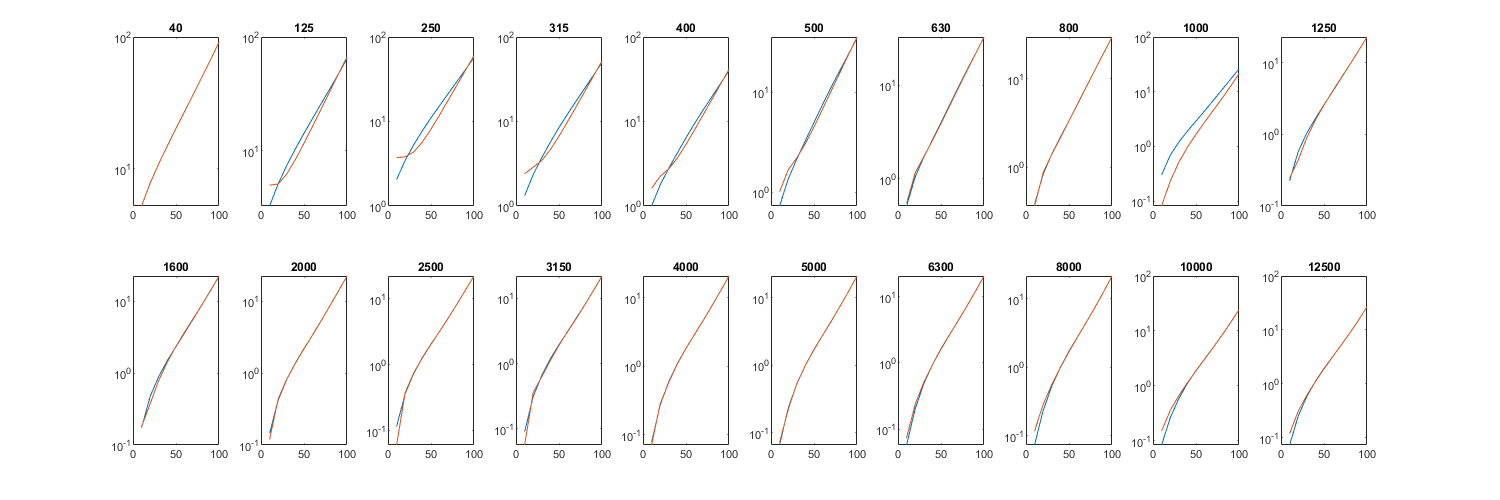


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% optimisation of other critical bands

% % initial parameter values
x0 = [0.107737844, 8.838319334, 0.100890616, 0.181733473, -0.062054578, 75.34197668, -109.1450155;
      0.040135337, -2.181006406, 0.108673519, 0.211990218, -0.009312837, 94.07961678, -19.0019942;
      0.055940743, 1.0, 0.4, 0.219924308, -0.01664898, 116.605044, -42.32829989;
      0.073176551, 0.5, 0.5, 0.202536774, -0.007097562, 89.5721625, -15.78716594;
      0.092115643, 1.149999999, 0.300000001, 0.196182779, -0.008927165, 90.24311787, -19.74458355;
      0.117916508, 1.149994005, 0.300009837, 0.187107973, -0.012015454, 88.1214034, -25.60404339;
      0.131306241, 1.19558383, 0.285915631, 0.186968293, -0.013872571, 90.16238218, -26.99737673;
      0.13941632, 1.201079272, 0.281264203, 0.18729956, -0.013560672, 91.81793046, -28.03120856;
      0.109431468, 1.159297862, 0.215960816, 0.210022629, -0.02138309, 118.9890784, -33.85091717;
      0.098905011, 0.463610787, 0.513888118, 0.194700276, -0.007953587, 99.2068481, -20.35050499;
      0.098160845, 0.763271806, 0.2, 0.198741374, -0.008868945, 101.0557993, -19.86652011;
      0.134433918, 0.778497926, 0.217416627, 0.192094268, -0.013627156, 104.9736866, -24.28401097;
      0.161114596, 1.27457493, 0.224108881, 0.187608559, -0.014572434, 102.7916212, -22.83179388;
      0.190709762, 15.8613793, 0.407493697, 0.198915826, -0.035147152, 115.5363546, -34.60952449;
      0.203884327, 2.080100574, 0.258795871, 0.190210851, -0.026977291, 109.6445913, -26.74024968;
      0.162669515, 1.077675378, 0.30474587, 0.184465972, -0.01410319, 102.5550921, -17.92639656;
      0.101922697, 1.077587567, 0.800001768, 0.193197089, -0.014393432, 112.1938718, -17.71426601;
      0.06825211, 0.09998681, 0.299722389, 0.221826309, -0.036569288, 128.2714066, -17.15079401;
      0.063823175, 0.099949504, 0.300558383, 0.217674237, -0.034408342, 125.9039073, -16.328818;
      0.06105491, 0.099802978, 0.303714288, 0.21129216, -0.030913821, 108.8187685, -4.568509235].';

% parameter bounds
lb = [0.01, 0.3, 0.1, 0.1, -0.07, 75, -108].';
ub = [0.25, 24, 0.9, 0.3, -.002, 140, -2].';

% optimisation loop over critical bands
optimFunc = @(q, X) loudnessTransform(X(:,1), X(:,2), q);
options = optimoptions('lsqcurvefit', 'MaxFunctionEvaluations', 1e5,...
                       'MaxIterations', 1e4,...
                       'Algorithm', 'interior-point');
q_optCB = zeros([length(q_opt1k), length(fnCB)]);
q_optCB(:, fnCB == 1000) = q_opt1k;
fig = figure;
tiledlayout(fig, 2, 10);
fig.Visible = 'on';
fig.Position = [50, 50, 1500, 500];
movegui(fig, 'center');

for ii = length(fnCB):-1:1

    if fnCB(ii) ~= 1000
        soneTarget = signal2soneCB(:, ii);

        [q_opt, resnorm, residual, exitflag, output] = ...
            lsqcurvefit(optimFunc, x0(:, ii), [phon2splCB(:, ii), repmat(levelThresQCB53233897(ii), length(phon2splCB(:, ii)), 1)],...
                        soneTarget, lb, ub, options);

        resnormCB(ii) = resnorm;
        q_optCB(:, ii) = q_opt;
    end
    
    ax = nexttile(ii);

    semilogy(phonRange, signal2soneCB(:, ii))
    hold on
    semilogy(phonRange, loudnessTransform(phon2splCB(:, ii), levelThresQCB53233897(ii), q_optCB(:, ii)))
    title(fnCB(ii))

end

% Optimisation of 1 kHz function for ISO 532-3 2.2-120 phon
x01k = [0.05, 0.5, 1.0, 0.293, -0.019679345, 117.1554108, -40.79234581];
lb1k = [0.045, 0.1, 0.1, 0.25, -0.1, 50, -100];
ub1k = [0.051, 0.8, 2, 0.35, -0.01, 120, -0.1];

phon2sone1kISO5323 = [0.001, 0.002, 0.004, 0.006, 0.014, 0.025, 0.066, 0.138, 0.252, 0.422, 0.664,...
                      1.000, 1.460, 2.090, 2.950, 4.110, 5.710, 7.920, 11.00, 15.40, 21.70,...
                      31.10, 44.70, 64.80, 94.30, 138.0, 205.0, 306.0].';

optimFunc = @(q, X) loudnessTransform(X(:,1), X(:,2), q);

options = optimoptions('lsqcurvefit', 'MaxFunctionEvaluations', 1e5, 'Algorithm', 'interior-point');

[q_opt1k5323, resnorm, residual, exitflag, output] = ...
    lsqcurvefit(optimFunc, x01k, [phonRange1k, repmat(levelThresQCB5323(fnCB == 1000), size(phonRange1k, 1), 1)],...
                phon2sone1kISO5323, lb1k, ub1k, options);


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% optimisation of other critical bands
[loudData5323File, loudData5323Path] = uigetfile("*.csv", "Select ISO5323Phon2SoneNoEar.csv file in \02 Delivery\Psychoacoustic metrics", inputPath);
loudData5323FilePath = fullfile(loudData5323Path, loudData5323File);

signal2sone5323Tab = readtable(loudData5323FilePath, 'ReadRowNames', true,...
                               'ReadVariableNames', true, 'VariableNamingRule', 'preserve');

signal2sone5323 = signal2sone5323Tab{:, :};

% initial parameter values
x0 = [0.008289487, 0.499996271, 0.549998317, 0.342032628, -0.036247778, 68.66938088, -53.73016187;
      0.034349331, 0.519, 0.546099975, 0.302106935, -0.010511661, 97.40586906, -17.21324533;
      0.048085996, 0.25, 0.280489223, 0.28685576, -0.009248863, 95.41843567, -15.10887319;
      0.052819958, -0.3, 0.100035379, 0.282579405, -0.010827924, 95.79321466, -17.48957246;
      0.056202154 -0.3, 0.100035696, 0.279932836, -0.011407079, 95.64954752, -18.4913392;
      0.060378483, -0.3, 0.100688464, 0.276436244, -0.013802732, 99.87968095, -22.47099597;
      0.055148571, -0.5, 0.295806557, 0.279167017, -0.005568983, 93.43844528, -11.22017513;
      0.060326185, -0.4, 0.100026681, 0.27582255, -0.009719933, 96.3426354, -19.00087229;
      0.056240214, -0.431956329, 0.10017493, 0.275445764, -0.006269643, 94.06205763, -14.28777726;
      0.056240214, -0.431956329, 0.10017493, 0.275445764, -0.006269643, 94.06205763, -14.28777726;
      0.05912088, -0.304181474, 0.096641999, 0.274355827, -0.00593841, 94.65498408, -14.98234127;
      0.059707345, -0.32163715, 0.091373494, 0.272195311, -0.006148646, 91.95400275, -17.55498083;
      0.061726564, -0.432988957, 0.100027898, 0.269917136, -0.003946778, 88.52896846, -12.55303159;
      0.065664161, -0.467981832, 0.100024428, 0.266097485, -0.003385879, 87.2040188, -13.23235303;
      0.166326818, -0.453452187, 0.166651431, 0.199215999, -0.061999118, 63.86680782, -81.98824535;
      0.063226907, -0.3, 0.129537853, 0.313539126, -0.047037434, 145.359289, -14.11964714;
      0.07, -0.3, 0.100000922, 0.308403586, -0.047984582, 115.3405964, -1.978953154;
      0.075841378, -0.3, 0.2, 0.248860592, -2.2585E-06, 165.7531658, -65.89221046;
      0.08, -0.5, 0.100000779, 0.234312792, -1.30e-06, 186.4760497, -69.01944269;
      0.098534243, -0.415788708, 0.100001077, 0.268524014, -0.049400694, 168.0292412, -7.090713621].';

% parameter bounds
lb = [0.004, -0.35, 0.05, 0.2, -3e-2, 20, -50];
ub = [0.09, -0.2, 1, 0.4, -1e-3, 150, -5];

% lb = [0.004, -0.35, 0.4, 0.3, -2e-2, 20, -50;
%       0.01, -0.35, 0.5, 0.2, -2e-2, 20, -25;
%       0.02, -0.35, 0.5, 0.2, -2e-2, 20, -25;
%       0.02, -0.35, 0.5, 0.2, -2e-2, 20, -25;
%       0.03, -0.35, 0.05, 0.2, -2e-2, 20, -25;
%       0.03, -0.38, 0.05, 0.2, -2e-2, 20, -30;
%       0.03, -0.35, 0.05, 0.2, -2e-2, 20, -30;
%       0.03, -0.35, 0.05, 0.2, -1e-2, 20, -25;
%       0.03, -0.35, 0.05, 0.2, -3e-2, 50, -50;
%       0.03, -0.38, 0.05, 0.2, -1e-2, 20, -30;
%       0.03, -0.38, 0.05, 0.2, -1e-2, 20, -30;
%       0.03, -0.35, 0.05, 0.2, -1e-2, 20, -30;
%       % 0.03, -0.35, 0.05, 0.2, -1e-2, 20, -30;
%       0.03, -0.35, 0.05, 0.2, -1e-2, 20, -30;
%       0.005, -0.35, 0.1, 0.2, -1e-1, 0.1, -100;
%       0.005, -0.35, 0.1, 0.2, -1e-1, 0.1, -100;
%       0.005, -0.35, 0.1, 0.2, -1e-1, 0.1, -100;
%       0.005, -0.35, 0.1, 0.2, -1e-1, 0.1, -100;
%       0.005, -0.35, 0.1, 0.2, -1e-1, 0.1, -100;
%       0.005, -0.35, 0.1, 0.2, -1e-1, 0.1, -100].';
% ub = [0.009, -0.2, 0.6, 0.4, -1e-3, 120, -10;
%       0.05, -0.2, 1.0, 0.4, -1e-3, 120, -10;
%       0.06, -0.2, 1.0, 0.4, -1e-3, 120, -10;
%       0.06, -0.2, 1.0, 0.4, -1e-3, 120, -5;
%       0.07, -0.25, 0.2, 0.4, -1e-2, 120, -10;
%       0.07, -0.25, 0.2, 0.4, -1e-2, 120, -10;
%       0.08, -0.2, 0.2, 0.4, -1e-2, 120, -10;
%       0.07, -0.2, 0.2, 0.4, -1e-3, 120, -5;
%       0.07, -0.2, 0.2, 0.4, -1e-2, 150, -10;
%       0.07, -0.25, 0.2, 0.4, -1e-3, 120, -5;
%       0.07, -0.25, 0.2, 0.4, -1e-3, 120, -5;
%       0.07, -0.2, 0.2, 0.4, -1e-3, 120, -5;
%       % 0.08, -0.25, 0.2, 0.4, -5e-4, 120, -5;
%       0.09, -0.25, 0.2, 0.4, -5e-4, 120, -5;
%       0.1, -0.2, 1.4, 0.4, -1e-7, 200, -0.1;
%       0.1, -0.2, 1.4, 0.4, -1e-7, 200, -0.1;
%       0.1, -0.2, 1.4, 0.4, -1e-7, 200, -0.1;
%       0.1, -0.2, 1.4, 0.4, -1e-7, 200, -0.1;
%       0.1, -0.2, 1.4, 0.4, -1e-7, 200, -0.1;
%       0.1, -0.2, 1.4, 0.4, -1e-7, 200, -0.1].';

options = optimoptions('lsqcurvefit', 'MaxFunctionEvaluations', 1e5,...
                       'Algorithm', 'interior-point');

% optimisation loop over critical bands
signal2soneCB5323 = [signal2sone5323(:, 4), signal2sone5323(:, 9), signal2sone5323(:, 12:end)];
q_optCB5323 = zeros([length(q_opt1k5323), length(fnCB)]);
q_optCB5323(:, fnCB == 1000) = q_opt1k5323;
for ii = length(fnCB):-1:1

    if fnCB(ii) == 1000
        continue
    else
        soneTarget = signal2soneCB5323(:, ii);

        [q_opt5323, resnorm, residual, exitflag, output] = ...
            lsqcurvefit(optimFunc, x0(:, ii), [phon2splCB(:, ii), repmat(levelThresQCB5323(ii), length(phon2splCB(:, ii)), 1)],...
                        soneTarget, lb, ub, options);

        resnormCB5323(ii) = resnorm;
        q_optCB5323(:, ii) = q_opt5323;
    end
end


Feasible point with lower objective function value found.


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Functions

function sone = loudnessTransform(splCB, ltqCB, q)
    q1 = q(1);
    q2 = q(2);
    q3 = q(3);
    q4 = q(4);
    q5 = q(5);
    q6 = q(6);
    q7 = q(7);
    
    q0 = q2.*exp(-q3.*splCB) + q4 + q5.*tanh((splCB - q6)/q7);
    sone = q1*(10.^(0.1*ltqCB)).^q0.*((1 - 0.25 + 0.25.*(10.^((splCB - ltqCB)./10))).^q0 - 1);
    sone = sone.*exp(0.98454256);

end
